Jack Martin

Colorado School of Mines

SEED Lab

2/5/2024

motor:

clc;

%% variables %%
K0 = 0.307 * 1600; % DC gain (tps/V)
sig0 = 14; % time constant reciprocal (1/s)
K1 = 0.27 * 1600; % DC gain (tps/V)
sig1 = 19; % time constant reciprocal (1/s)

%% test %%
tps0 = [0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 759.88, 1141.55, 1445.09, 1552.80, 1798.56, 1748.25, 1798.56, 1773.05, 1824.82, 1838.24, 1953.13, 1908.40, 1879.70, 1908.40, 1893.94, 1937.98, 2083.33, 1923.08, 1908.40, 1953.13, 1953.13, 2049.18, 2066.12, 2032.52, 1923.08, 1865.67, 1968.50, 1923.08, 1879.70, 1937.98, 1908.40, 1811.59, 2083.33, 1984.13, 2083.33, 1984.13, 1923.08, 1851.85, 1893.94, 1865.67, 1865.67, 1908.40, 1923.08, 1984.13, 2066.12, 1937.98, 2100.84, 1953.13, 1893.94, 1879.70, 1811.59, 1923.08, 1893.94, 2049.18, 2049.18, 2100.84, 1923.08, 1968.50, 1838.24, 1851.85, 1851.85, 1865.67, 1865.67, 1824.82, 1923.08, 1968.50, 2066.12, 2000.00, 1923.08, 2100.84, 1824.82, 1908.40, 1879.70, 2032.52, 2000.00, 1937.98, 2032.52, 2032.52, 2118.64, 2000.00, 2083.33, 2000.00, 1968.50, 2000.00];
volt0 = [0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98];
tps1 = [0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 791.14, 976.56, 1308.90, 1373.63, 1562.50, 1612.90, 1724.14, 1773.05, 1736.11, 1700.68, 1773.05, 1689.19, 1785.71, 1748.25, 1712.33, 1724.14, 1748.25, 1798.56, 1760.56, 1760.56, 1724.14, 1689.19, 1700.68, 1760.56, 1623.38, 1700.68, 1748.25, 1748.25, 1748.25, 1736.11, 1785.71, 1724.14, 1736.11, 1785.71, 1666.67, 1724.14, 1689.19, 1748.25, 1748.25, 1724.14, 1666.67, 1785.71, 1760.56, 1677.85, 1748.25, 1798.56, 1666.67, 1700.68, 1748.25, 1666.67, 1724.14, 1785.71, 1677.85, 1655.63, 1736.11, 1700.68, 1798.56, 1724.14, 1798.56, 1748.25, 1760.56, 1623.38, 1700.68, 1785.71, 1760.56, 1689.19, 1689.19, 1655.63, 1748.25, 1798.56, 1724.14, 1773.05, 1700.68, 1736.11, 1689.19, 1644.74, 1736.11, 1712.33, 1736.11, 1736.11, 1785.71, 1712.33, 1798.56, 1689.19];
volt1 = [0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 0.00, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98, 3.98];
t = linspace(0, 3, 128);

%% simulation %%
open_system('motor') % open simulink system
out = sim('motor') % run simulation

out =   Simulink.SimulationOutput:

                   tout: [55x1 double] 
              velocity0: [1x1 timeseries] 
              velocity1: [1x1 timeseries] 
               voltage0: [1x1 timeseries] 
               voltage1: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 



%% results %%
% motor0:
disp("//////// motor0 ////////")

//////// motor0 ////////


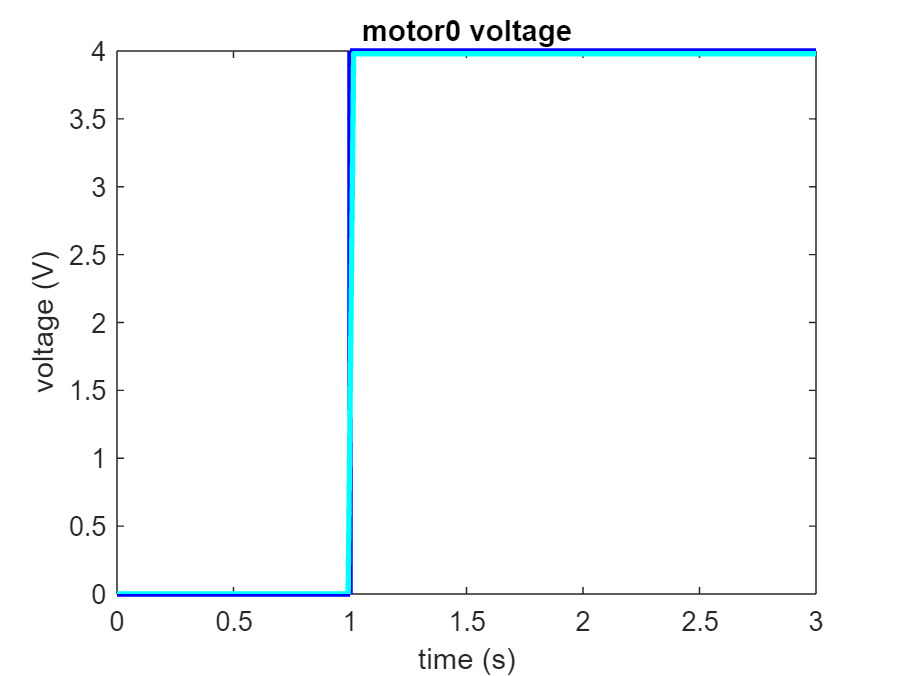

plot(out.voltage0, 'linewidth', 2, 'color', 'blue')
hold on
plot(t, volt0, 'linewidth', 2, 'color', 'cyan')
hold off
xlabel('time (s)')
ylabel('voltage (V)')
title("motor0 voltage")

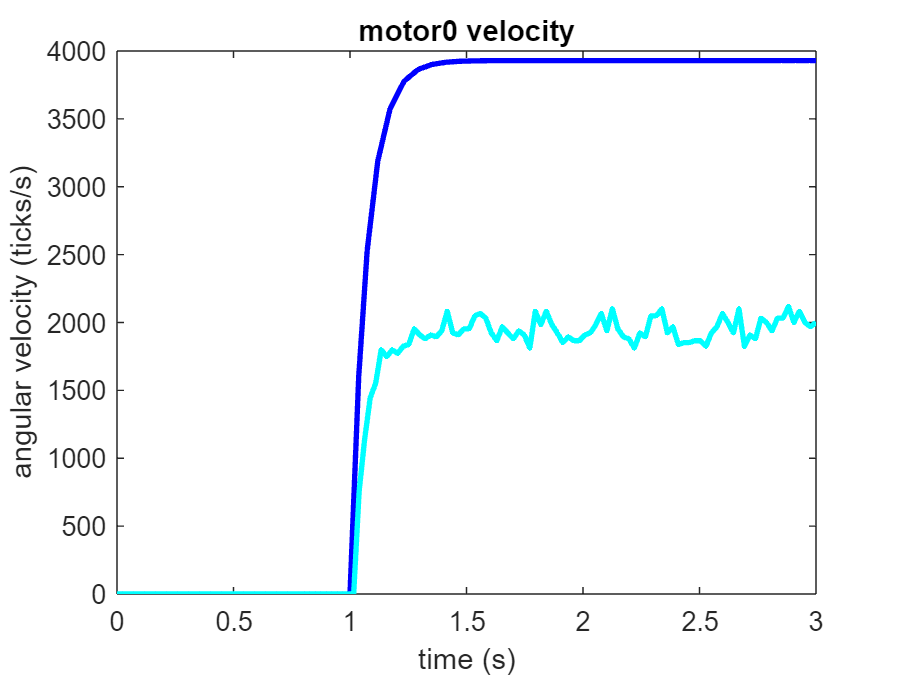

plot(out.velocity0, 'linewidth', 2, 'color', 'blue')
hold on
plot(t, tps0, 'linewidth', 2, 'color', 'cyan')
hold off
xlabel('time (s)')
ylabel('angular velocity (ticks/s)')
title('motor0 velocity');

% motor1:
disp("//////// motor1 ////////")

//////// motor1 ////////


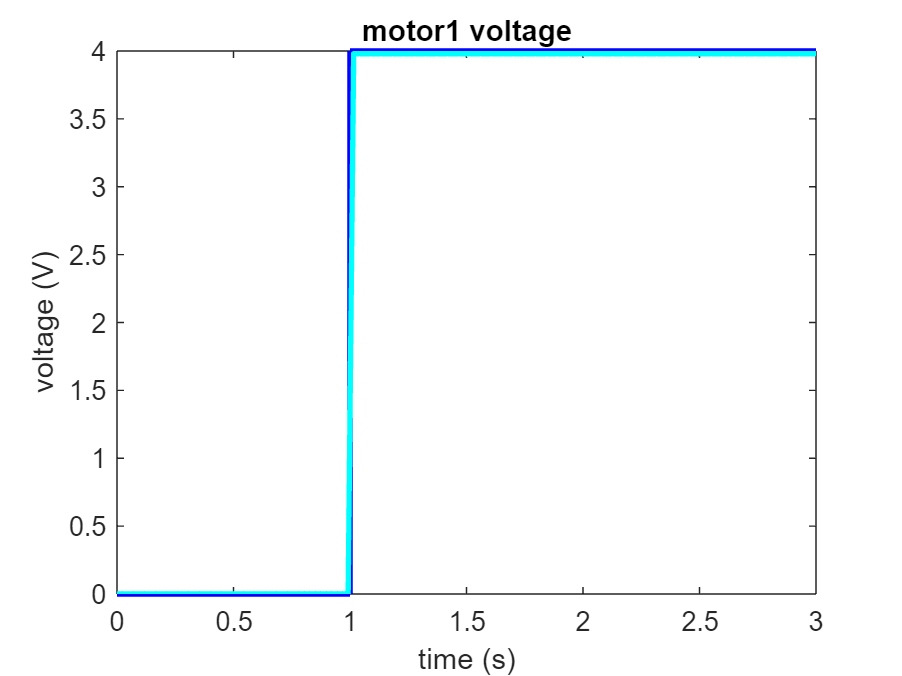

plot(out.voltage1, 'linewidth', 2, 'color', 'blue')
hold on
plot(t, volt1, 'linewidth', 2, 'color', 'cyan')
hold off
xlabel('time (s)')
ylabel('voltage (V)')
title("motor1 voltage")

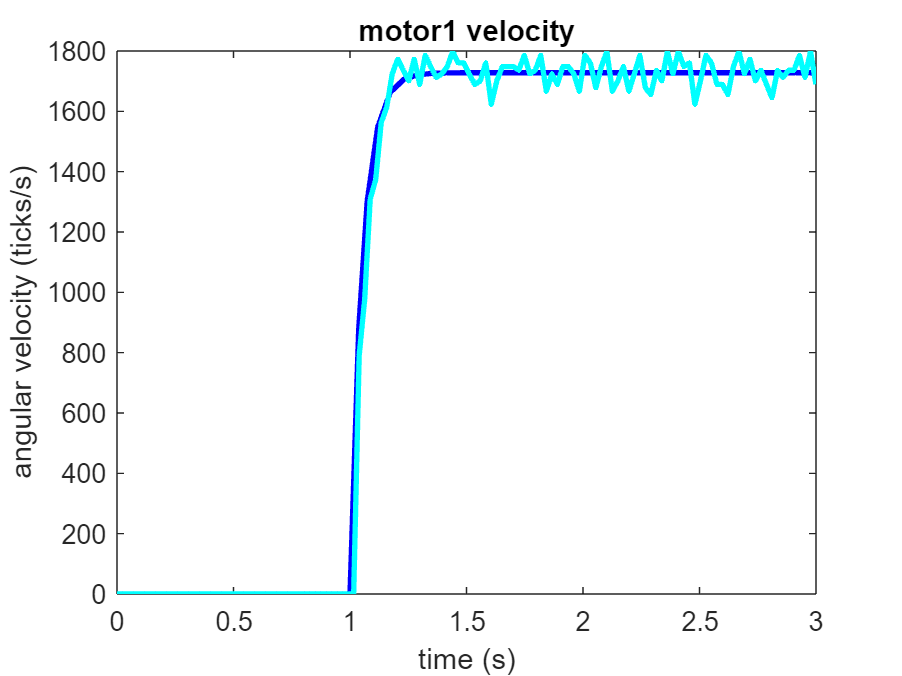

plot(out.velocity1, 'linewidth', 2, 'color', 'blue')
hold on
plot(t, tps1, 'linewidth', 2, 'color', 'cyan')
hold off
xlabel('time (s)')
ylabel('angular velocity (ticks/s)')
title('motor1 velocity');